Question 6) Controller Pole Placement

% Define reference values
Href = 0.3048 * 30000;  % 30,000 ft in meters
Mref = 0.6;         % Mach number

% Augment the system to include height h and mach number m
x6 = {'u', 'w', 'q', 'theta', 'm', 'h'};
y6 = {'mach number', 'height'};

A_a = zeros(6,6);
A_a(1:4,1:4) = a1;
A_a(5:6,1:6) = zeros(2,6);
A_a(6,1:4) = [0, 1, 0, 0]; % dh/dt = y velocity
A_a(5,1:4) = a1(1,1:4)/343; % Approximation
A_a(5,1:4) = a1(1,1:4)/343; % Approximation
B_a = [b1; [b1(1,1:2)/343; 0 0]]; % Approximation
%B_a = [b1; [b1(1,1)/343 0; 0 0]]; % Approximation
C_a = [0 0 0 0 1 0; 0 0 0 0 0 1];

sys_mimo6 = ss(A_a,B_a,C_a,0,'statename',x6,...
'inputname',u1,...
'outputname',y6);

Ob = obsv(sys_mimo6);
Co = ctrb(sys_mimo6);
rank(Ob)

ans = 6

rank(Co)

ans = 5

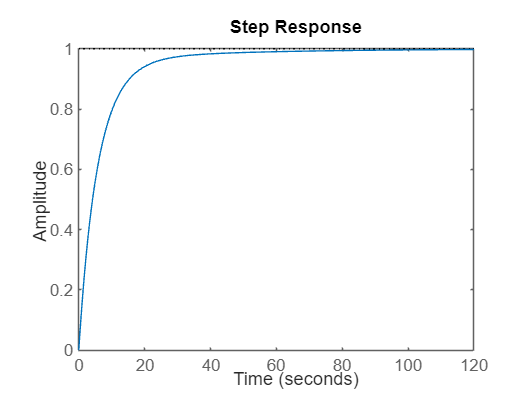


mnSE  = tf(sys_mimo6(1,1));
hSE = tf(sys_mimo6(2,1));
mnST  = tf(sys_mimo6(1,2));
hST = tf(sys_mimo6(2,2));

s = tf('s');

tMM = .05;
tTS = 5;
tES = .02;
tA = .8;

delayMM = (1/tMM)/(s + (1/tMM));
delayTS = (1/tTS)/(s + (1/tTS)); 
delayES = (1/tES)/(s + (1/tES));
delayA = (1/tA)/(s + (1/tA));

tol = 1e-3;

GmMref = minreal(delayTS*mnST, tol);
GmHref = minreal(delayES*mnSE, tol);
GhMref = minreal(delayTS*hST, tol);
GhHref = minreal(delayES*hSE, tol);

%C1 = -20*(s - .0962 + .1026*1i)*(s - .0962 - .1026*1i);
C1 = 3*(s+.2)*(s^2 - 0.1924*s + 0.01978)*(s+.025)/(s*(s-0.1435)*(s-0.005787));
C2 = .2*(s^2 - 0.1924*s + 0.01978)/(s*(s+25));

C3 = -79e-3*(s^2 - 0.1924*s + 0.01978)*(s+.2)*(s+.03)/((s-.0048654)*(s-5.4425));
C4 = 3e-5*(s^2 - 0.1924*s + 0.01978)*(s+.03)/((s-41.475)*(s^2 - 0.003694*s + 0.0006934));

TmMref = minreal(GmMref*C1 / (1 + delayMM*GmMref*C1), tol);
step(TmMref)

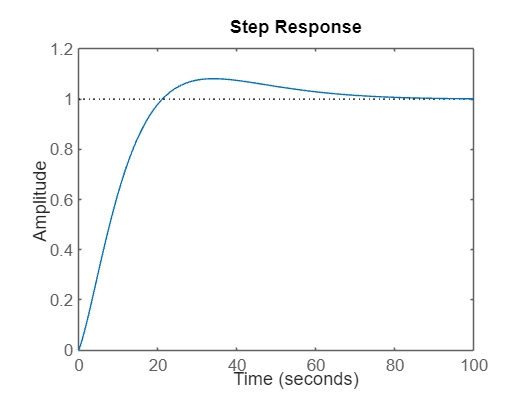

%rlocus(minreal(delayMM*GmMref*C1, tol))
[xx1, yy1] = pzmap(minreal(GmMref*C1, tol));
[x1, y1] = pzmap(TmMref)

TmHref = minreal(GmHref*C2 / (1 + delayA*GmHref*C2), tol);
step(TmHref)

%rlocus(minreal(delayA*GmHref*C2, tol))
[xx2, yy2] = pzmap(minreal(GmHref*C2, tol));
[x2, y2] = pzmap(TmHref)

x2 =  -50.0013 + 0.0000i
 -24.9996 + 0.0000i
  -1.2195 + 0.0000i
  -0.2127 + 0.0000i
  -0.0749 + 0.0300i
  -0.0749 - 0.0300i


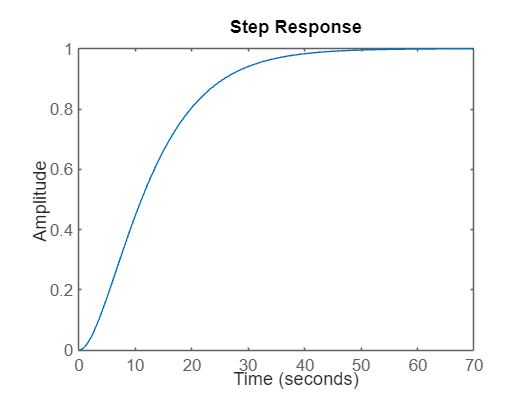


ThMref = minreal(GhMref*C3 / (1 + delayMM*GhMref*C3), tol);
step(ThMref) 

%rlocus(minreal(delayMM*GhMref*C3,tol))
[xx3, yy3] = pzmap(minreal(GhMref*C3, tol));
[x3, y3] = pzmap(ThMref)

x3 =   -0.1509 + 0.0068i
  -0.1509 - 0.0068i



y3 =

  0×1 empty double column vector



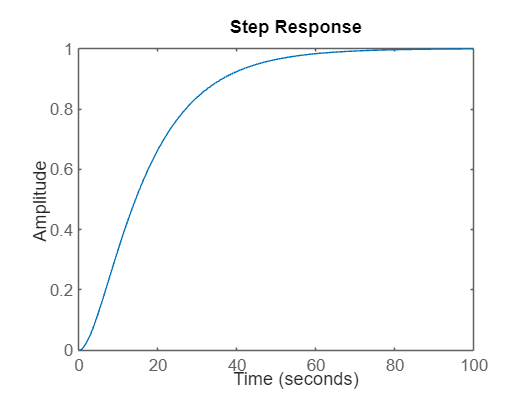


ThHref = minreal(GhHref*C4 / (1 + delayA*GhHref*C4), tol);
step(ThHref)

%rlocus(minreal(delayA*GhHref*C4, tol))
[xx4, yy4] = pzmap(minreal(GhHref*C4, tol));
[x4, y4] = pzmap(ThHref)

y4 = -1.2500

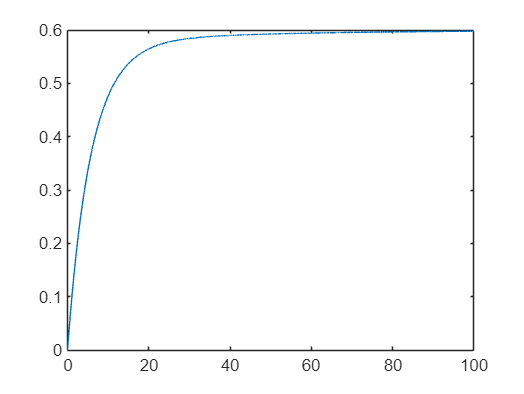


optH = RespConfig;
optH.Amplitude = Href;

optM = RespConfig;
optM.Amplitude = Mref;


% Define reference values
Href = 0.3048 * 30000;  % 30,000 ft in meters
Mref = 0.6;             % Mach number

% Time vector for simulation
t = 0:0.1:100;

% Create RespConfig objects for step amplitudes
optM = RespConfig;
optM.Amplitude = Mref;  % Step amplitude for Mach number reference

optH = RespConfig;
optH.Amplitude = Href;  % Step amplitude for height reference
t = 0:0.01:100;

plot(t, step(TmMref, t, optM)+ 0*step(TmHref, t, optH))

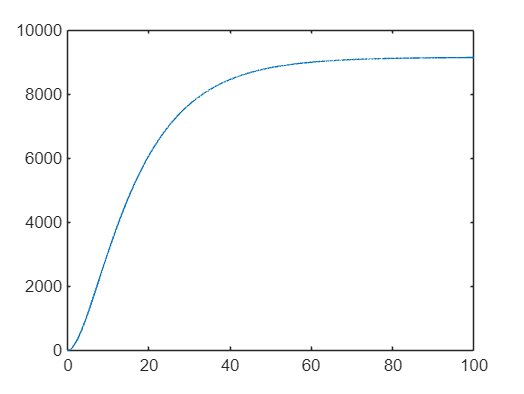

plot(t, step(ThHref, t, optH)+ 0*step(ThMref, t, optM))

Question 7) Model Perdictive Control

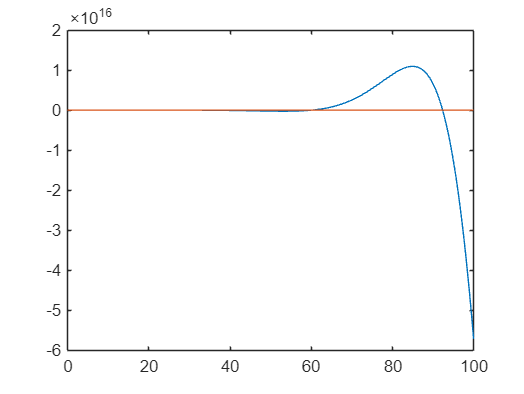

s = tf('s');

Hs = 0.3048 * 30000;
Href = 0.3048 * 32000;

a = 1/.8;
b = 1/.02;

delayE = b / (s + b);
delayA = a / (s + a);

% Augment the system to include height h
x7 = {'u', 'w', 'q', 'theta', 'h'};
y7 = {'height'};
r7 = {'Href'};

A_a7 = zeros(5,5);
A_a7(1:4,1:4) = a1;
A_a7(5,1:4) = [0, 1, 0, 0]; % dh/dt = y velocity
B_a7 = [b1(:,1); 0 ];
C_a7 = [0 0 0 0 1];

sys_siso7 = ss(A_a7,B_a7,C_a7,Hs,'statename',x7,...
'inputname',r7,...
'outputname',y7);

am = A_a7;
bm = B_a7;
cm = C_a7;

np = 8;
nc = 3;
R = 0.1;

ts = 0.1;

a = eye(5);
b = eye(5)*ts;

for k = 1:100
    a = a + am^k*ts^k/factorial(k);
end

for k = 1:100
    b = b + am^k*ts^(k+1)/factorial(k+1);
end
b=b*bm;

A = [a zeros(5,1); cm*a 1];
B = [b; cm*b];
C = [0 0 0 0 0 1];

F = C*A;
for k = 2:np
    F = [F; C*A^k];
end

Th = zeros(np,nc);

for j = 1:np
    for k = 1:nc
        Th(j,k) = C*A^(j-k)*B;
    end
end
Th(1,nc) = 0;

% Reference altitude
Href = 0.3048 * 32000; % 9753.6 meters
Rs = Href * ones(np, 1);

% Simulation parameters
Tsim = 100; % Simulation time in seconds
Nsim = Tsim / ts; % Number of simulation steps
x = [9144; 0; 0; 0; 0]; % Initial state: h = 9144 m, others 0
x_aug = [x; 0]; % Augmented state with integral error
h_history = zeros(Nsim, 1); % Store altitude
u_history = zeros(Nsim, 1); % Store control input
t = (0:Nsim-1) * ts; % Time vector

% Simulate the system
for k = 1:Nsim
    % Compute control input
    m1 = Th' * Th + R * eye(nc);
    m2 = Th' * F;
    m3 = Th' * Rs;
    U = m1 \ (m3 - m2 * x_aug);
    u = U(1); % Apply the first control input
    
    % Update the state
    x = a * x +b * u;
    x_aug = A * x_aug + C * u;
    
    % Store results
    h_history(k) = cm * x;
    u_history(k) = u;
end

plot(t, h_history,t, u_history)